# Question 6

Answers at end of this script

## DOWNCONVERSION

clear; clc;

fs = 8000; % Hz
Ts = 1/fs;
N = 4096;
t = (0:N-1)*Ts;

% Pick a tone that will alias after downsampling
f0 = 0.35*fs; % 2.8 kHz
x = cos(2*pi*f0*t);

% downsample by M=2
M = 2;
y = x(1:M:end);
fs_y = fs/M;
Ty = 1/fs_y;

% Zero padding
yZ = zeros(1,N);
yZ(1:length(y)) = y;

X = fftshift(fft(x, N));
Y = fftshift(fft(yZ, N));
fx = linspace(-fs/2, fs/2, N);
fy = linspace(-fs_y/2, fs_y/2, N);

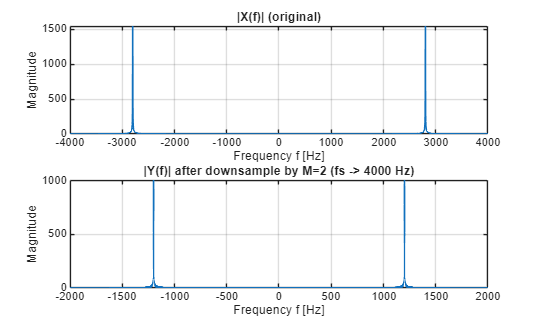

figure('Color','w');
subplot(2,1,1); plot(fx, abs(X), 'LineWidth',1.2); grid on;
title('|X(f)| (original)'); xlabel('Frequency f [Hz]'); ylabel('Magnitude');

subplot(2,1,2); plot(fy, abs(Y), 'LineWidth',1.2); grid on;
title(sprintf('|Y(f)| after downsample by M=%d (fs -> %.0f Hz)', M, fs_y));
xlabel('Frequency f [Hz]'); ylabel('Magnitude');

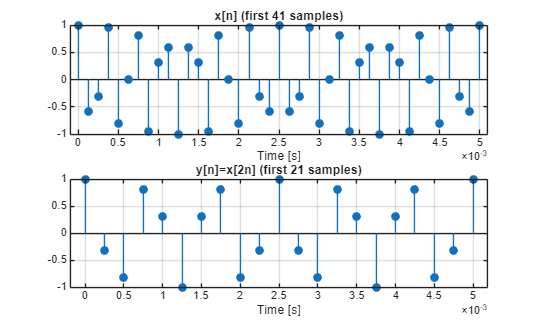

% time domain view
figure('Color','w');
subplot(2,1,1);
stem(t(1:41), x(1:41), 'filled'); grid on;
title('x[n] (first 41 samples)'); xlabel('Time [s]');

subplot(2,1,2);
ty = (0:length(y)-1)*Ty;
stem(ty(1:21), y(1:21), 'filled'); grid on;
title('y[n]=x[2n] (first 21 samples)'); xlabel('Time [s]');

## UPSAMPLING

clear; clc;

fs = 8000;
Ts = 1/fs;
N = 4096;
t = (0:N-1)*Ts;

% Tone that is clear after upsampling
f0 = 0.15*fs; % 1200 Hz for fs = 8 kHz
x = cos(2*pi*f0*t);

% Upsample
L = 3;
xu = zeros(1, L*length(x));
xu(1:L:end) = x;

fs_u = L*fs;
Tu = 1/fs_u;
Nu = L*N;

X = fftshift(fft(x,N));
Xu = fftshift(fft(xu, Nu));
fx = linspace(-fs/2, fs/2, N);
fu = linspace(-fs_u/2, fs_u/2, Nu);

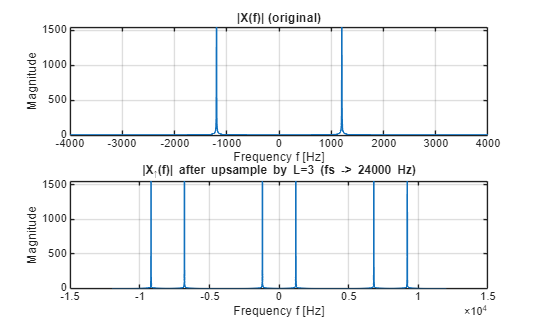

figure('Color','w');
subplot(2,1,1); plot(fx, abs(X), 'LineWidth',1.2); grid on;
title('|X(f)| (original)'); xlabel('Frequency f [Hz]'); ylabel('Magnitude');

subplot(2,1,2); plot(fu, abs(Xu), 'LineWidth',1.2); grid on;
title(sprintf('|X_{\\uparrow}(f)| after upsample by L=%d (fs -> %.0f Hz)', L, fs_u));
xlabel('Frequency f [Hz]'); ylabel('Magnitude');

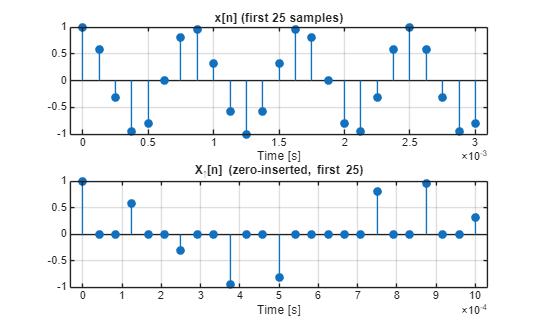

% time domain view
figure('Color','w');
subplot(2,1,1);
stem(t(1:25), x(1:25), 'filled'); grid on;
title('x[n] (first 25 samples)'); xlabel('Time [s]');

subplot(2,1,2);
tu = (0:length(xu)-1)*Tu;
stem(tu(1:25), xu(1:25), 'filled'); grid on;
title('X_{\uparrow}[n] (zero-inserted, first 25)'); xlabel('Time [s]');

## ANSWERS

Downsampling

- The new apparent tone frequency is at 1200 Hz

- |Y(f)| looks compressed/overlapped near the base of the tone peak because original tone has folded into the upper and lower frequencies, due to the decrease in sampling frequency when downsampling.

- The bandlimit on |X(f)| to avoid aliasing for M=2 is less than 1/4 the original sample frequency. For original fs = 8000 Hz, the highest frequency |X(f)| is 2000 Hz. When downsampling occurs and the new sampling frequency is 4000 Hz, no aliasing will occur as |X(f)| fuffils the Nyquist-Shannon sampling theorem.

Upsampling

- 3 images appear, although one is the same as the original |X(f)| at +/- 1.2 kHz.

- The other two images are +/- 8000 Hz from 0 Hz, which was the original sampling frequency fs. Each image also contains 2 tones, each one at +/- 8.0 kHz +/- 1.2 kHz.

- A low-pass filter with cutoff frequency of ~1.5 kHz would attenuate the outer images, leaving only the original. 